%%Clase 1 - Introducción al MEF con cálculo matricial.
% Parámetros del problema %
%A=1; E=1; L=1; P=100; gamma=pi/4;
A= 1E-4; E=70E9; L=1; P=1E4; gamma=pi/4; %Parámetros realistas

% Variables a reutilizar en el problema - eficiencia cálculo
Ke = E*A * [1 0 -1 0; 0 0 0 0;-1 0 1 0; 0 0 0 0]; %%Matriz de rigidez local de barras (multiplicada por longitud)

% Coordenadas de los nodos
n1 = [0, L/2];
n2 = [0, 0];
n3 = [0, -L];
n4 = [L, 0];


Cálculo de matrices de rigidez por elemento en coordenadas globales.

%% Elemento 1

Le1 = L * sqrt(5/4);
alpha1 = -atan((L/2)/L);
Re1 = [cos(alpha1) sin(alpha1); -sin(alpha1) cos(alpha1)]; %%Matriz de rotación de dos grados de libertad = 1 nodo
Re1_ = [Re1 zeros(2);zeros(2) Re1]; %%Matriz de rotación total, correspondiente a cuatro grados de libertad = 2 nodos

Ke1 = Ke * Le1;
Ke1_ = Re1_' * Ke1 * Re1_

Ke1_ = 1.0e+06 *

    6.2610   -3.1305   -6.2610    3.1305
   -3.1305    1.5652    3.1305   -1.5652
   -6.2610    3.1305    6.2610   -3.1305
    3.1305   -1.5652   -3.1305    1.5652



%% Elemento 2

Le2 = L;
alpha2 = 0;
Re2 = [cos(alpha2) sin(alpha2); -sin(alpha2) cos(alpha2)]; %%Matriz de rotación de dos grados de libertad = 1 nodo x->x'
Re2_ = [Re2 zeros(2);zeros(2) Re2]; %%Matriz de rotación total, correspondiente a cuatro grados de libertad = 2 nodos

Ke2 = Ke * Le2;
Ke2_ = Re2_' * Ke2 * Re2_

Ke2_ =      7000000           0    -7000000           0
           0           0           0           0
    -7000000           0     7000000           0
           0           0           0           0



%% Elemento 3

Le3 = L * sqrt(2);
alpha3 = pi / 4;
Re3 = [cos(alpha3) sin(alpha3); -sin(alpha3) cos(alpha3)]; %%Matriz de rotación de dos grados de libertad = 1 nodo
Re3_ = [Re3 zeros(2);zeros(2) Re3]; %%Matriz de rotación total, correspondiente a cuatro grados de libertad = 2 nodos

Ke3 = Ke * Le3;
Ke3_ = Re3_' * Ke3 * Re3_

Ke3_ = 1.0e+06 *

    4.9497    4.9497   -4.9497   -4.9497
    4.9497    4.9497   -4.9497   -4.9497
   -4.9497   -4.9497    4.9497    4.9497
   -4.9497   -4.9497    4.9497    4.9497


## Ensamblaje de elementos

gdl_e1 = [1 2 7 8]; %%grados de libertad de e1
gdl_e2 = [3 4 7 8]; %%grados de libertad de e2
gdl_e3 = [5 6 7 8]; %%grados de libertad de e3

K = zeros(8); %%declaración de matriz de rigidez de la estructura vacía

K(gdl_e1,gdl_e1) = K(gdl_e1,gdl_e1) + Ke1_; %%ensamblaje de e1 en la estructura en coordenadas globales.
K(gdl_e2,gdl_e2) = K(gdl_e2,gdl_e2) + Ke2_; %%ensamblaje de e2 en la estructura en coordenadas globales.
K(gdl_e3,gdl_e3) = K(gdl_e3,gdl_e3) + Ke3_; %%ensamblaje de e3 en la estructura en coordenadas globales.

K %%Matriz de rigidz completa en globales

K = 1.0e+07 *

    0.6261   -0.3130         0         0         0         0   -0.6261    0.3130
   -0.3130    0.1565         0         0         0         0    0.3130   -0.1565
         0         0    0.7000         0         0         0   -0.7000         0
         0         0         0         0         0         0         0         0
         0         0         0         0    0.4950    0.4950   -0.4950   -0.4950
         0         0         0         0    0.4950    0.4950   -0.4950   -0.4950
   -0.6261    0.3130   -0.7000         0   -0.4950   -0.4950    1.8211    0.1819
    0.3130   -0.1565         0         0   -0.4950   -0.4950    0.1819    0.6515


## Condensación de matrices para imponer C.C.


gdl = [1:8]; %% 4 nodos con grados de libertad en x,y
gdl_r = [1:6]; %%grados de libertad correspondientes a desplazamientos restringidos
gdl_l = setdiff(gdl, gdl_r); %%grados de libertad corespondientes a desplazamientos libres

Kll = K(gdl_l,gdl_l); %%Extraigo los elementos  correspondientes a grados libres.
Krl = K(gdl_r, gdl_l); %%Extraigo los elementos correspondientes a acoplamiento de grados restringidos/libres

%%%%
%% Inicio el cálculo de ul - mediante la expresion fl = Kll * ul + Klr * ur
%%%%
feq = zeros(8,1); %% Declaración de vector de fuerzas
gamma = pi/4;
fl = P*[cos(gamma);-sin(gamma)]

fl = 1.0e+03 *

    7.0711
   -7.0711


feq(gdl_l) = feq(gdl_l) + fl;
ul = Kll\fl %%Slash == inversión Kll Desplazamientos en nodo 4

ul =     0.0005
   -0.0012



%%%%
%% Paso ahora a calcular fuerzas mediante la expresión fr = Krr * ur + Krl * ul
%%%%
u = zeros(8,1); %vector de desplazamientos vacío
u(gdl_l) = u(gdl_l) + ul;
fr = Krl * ul;  %%fuerzas en grados restringidos:reacción
feq(gdl_r) = feq(gdl_r) + fr 

feq = 1.0e+03 *

   -7.0436
    3.5218
   -3.5768
         0
    3.5493
    3.5493
    7.0711
   -7.0711


## Representación

%%representación
axis equal
title('Estructura original y deformada elástica','FontSize',10);
xlabel('Posiciones nodales X','FontSize',10);
ylabel('Posiciones nodales Y','FontSize',10);
cnodos = [n1; n2; n3; n4];
escala = 0.25 * max(max(abs(cnodos)))/max(abs(u));
 
figure(1)
clf
hold on
%%represento elemento 1
plot([n1(1,1) n4(1,1)], [n1(1,2) n4(1,2)],'-bo')
%%represento elemento 1 deformado
ue1 = u(gdl_e1)

ue1 =          0
         0
    0.0005
   -0.0012


plot([n1(1,1) + ue1(1) * escala     n4(1,1) + ue1(3) * escala], [n1(1,2) + ue1(2) * escala  n4(1,2) + ue1(4) * escala ],'--r')

%%elemento 2
plot([n2(1,1) n4(1,1)], [n2(1,2) n4(1,2)],'-bo')
%%represento elemento 2 deformado
ue2 = u(gdl_e2)

ue2 =          0
         0
    0.0005
   -0.0012


plot([n2(1,1) + ue2(1) * escala     n4(1,1) + ue2(3) * escala], [n2(1,2) + ue2(2) * escala  n4(1,2) + ue2(4) * escala ],'--r')

%%elemento 3
plot([n3(1,1) n4(1,1)], [n3(1,2) n4(1,2)],'-bo')
%%represento elemento 3 deformado
ue3 = u(gdl_e3)

ue3 =          0
         0
    0.0005
   -0.0012


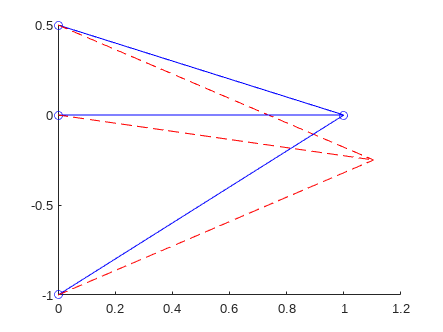

plot([n3(1,1) + ue3(1) * escala     n4(1,1) + ue1(3) * escala], [n3(1,2) + ue3(2) * escala  n4(1,2) + ue3(4) * escala ],'--r')